testowy 

detector = vision.CascadeObjectDetector();
RGB = imread('testowy_0_0000.jpeg');
bboxes = detector(RGB);
liczbaWykrytychTwarzy = size(bboxes,1)

liczbaWykrytychTwarzy = 1


GRAY=rgb2gray(RGB);
corners = detectMinEigenFeatures(GRAY);
corners

corners =   2455×1 cornerPoints array with properties:

    Location: [2455×2 single]
      Metric: [2455×1 single]
       Count: 2455


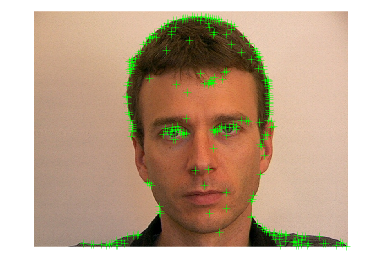

figure; imshow(RGB)
hold on; plot(corners.selectStrongest(250))

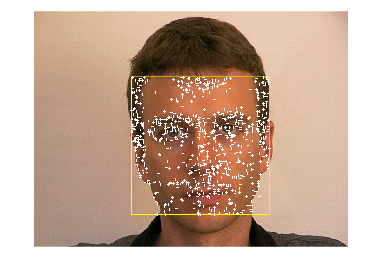


corners2 = detectMinEigenFeatures(GRAY, 'ROI', bboxes(1, :));
xyPoints = corners2.Location;
bboxPoints = bbox2points(bboxes(1, :));
bboxPolygon = reshape(bboxPoints', 1, []);
RGB2 = insertShape(RGB, 'Polygon', bboxPolygon, 'LineWidth', 3);
RGB2 = insertMarker(RGB2, xyPoints, '+', 'Color', 'white');
figure; imshow(RGB2)

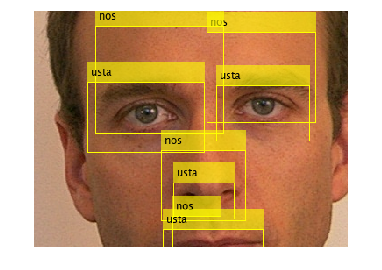


noseDetector = vision.CascadeObjectDetector('Nose');
mouthDetector = vision.CascadeObjectDetector('Mouth');
noseBBox1=step(noseDetector, RGB);
mouthBBox1=step(mouthDetector, RGB);
RGB2 = RGB;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox1,'nos');
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',mouthBBox1,'usta');
imshow(RGB2)

nos - 5

usta - 6

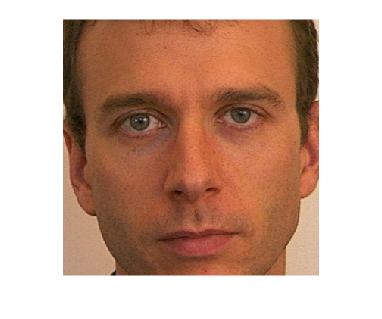

faceIM = imcrop(RGB, bboxes(1, :)); % wycięcie obszaru twarzy
imshow(faceIM)

% zawężenie detekcji cech tylko do obszaru twarzy
noseBBox2=step(noseDetector, faceIM);
mouthBBox2=step(mouthDetector, faceIM);
% dodatkowe warunki weryfikujące cechy
RGB2 = faceIM;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2,'nos');
figure;subplot(1,2,1);imshow(RGB2)
srodekTwarzy = [bboxes(1,3)/2 bboxes(1,4)/2]

srodekTwarzy =   168.5000  168.5000


% uwaga bboxes to wspolrzedne przed wycieciem twarzy
srodekNosa = [noseBBox2(:,1)+noseBBox2(:,3)/2 noseBBox2(:,2)+noseBBox2(:,4)/2]

srodekNosa =   162.5000  273.5000
  167.5000  219.0000
  235.5000   95.5000
  122.0000  106.0000


hold on
plot(srodekTwarzy(1),srodekTwarzy(2),'ro')
plot(srodekNosa(:,1),srodekNosa(:,2),'go')
proporcjaObszaruTwarzyiNosa = 0.3;
poleTwarzy = bboxes(1,3).*bboxes(1,4)

poleTwarzy = 113569

poleNosa = noseBBox2(:,3).*noseBBox2(:,4)

poleNosa =         2009
        7600
       17017
       20856


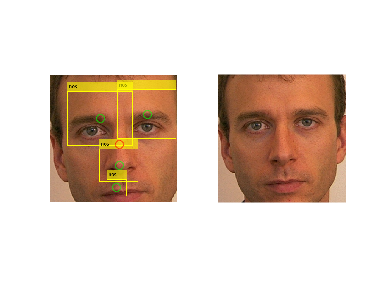

nos_warunek_1 = poleNosa > proporcjaObszaruTwarzyiNosa*poleTwarzy;
noseBBox2A = noseBBox2(nos_warunek_1,:);
RGB2 = faceIM;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2A,'nos');
subplot(1,2,2);imshow(RGB2)

algorytm poprawnie ograniczył do jednego nosa, ale znalazł 3 elementry w błędnych miejscach

własny 1

detector = vision.CascadeObjectDetector();
RGB = imread('snapshot1.png');
bboxes = detector(RGB);
liczbaWykrytychTwarzy = size(bboxes,1)

liczbaWykrytychTwarzy = 1


GRAY=rgb2gray(RGB);
corners = detectMinEigenFeatures(GRAY);
corners

corners =   1281×1 cornerPoints array with properties:

    Location: [1281×2 single]
      Metric: [1281×1 single]
       Count: 1281


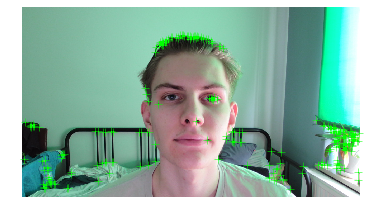

figure; imshow(RGB)
hold on; plot(corners.selectStrongest(250))

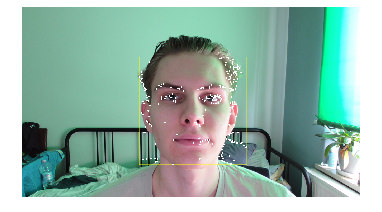


corners2 = detectMinEigenFeatures(GRAY, 'ROI', bboxes(1, :));
xyPoints = corners2.Location;
bboxPoints = bbox2points(bboxes(1, :));
bboxPolygon = reshape(bboxPoints', 1, []);
RGB2 = insertShape(RGB, 'Polygon', bboxPolygon, 'LineWidth', 3);
RGB2 = insertMarker(RGB2, xyPoints, '+', 'Color', 'white');
figure; imshow(RGB2)

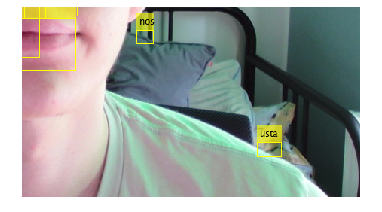


noseDetector = vision.CascadeObjectDetector('Nose');
mouthDetector = vision.CascadeObjectDetector('Mouth');
noseBBox1=step(noseDetector, RGB);
mouthBBox1=step(mouthDetector, RGB);
RGB2 = RGB;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox1,'nos');
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',mouthBBox1,'usta');
imshow(RGB2)

nos - 4

usta - 8

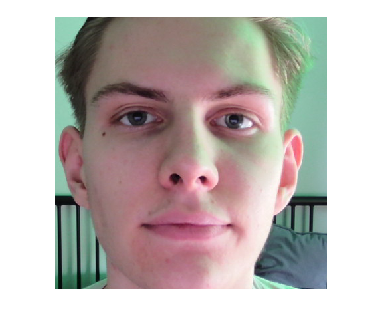

faceIM = imcrop(RGB, bboxes(1, :)); % wycięcie obszaru twarzy
imshow(faceIM)

% zawężenie detekcji cech tylko do obszaru twarzy
noseBBox2=step(noseDetector, faceIM);
mouthBBox2=step(mouthDetector, faceIM);
% dodatkowe warunki weryfikujące cechy
RGB2 = faceIM;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2,'nos');
figure;subplot(1,2,1);imshow(RGB2)
srodekTwarzy = [bboxes(1,3)/2 bboxes(1,4)/2]

srodekTwarzy =    204   204


% uwaga bboxes to wspolrzedne przed wycieciem twarzy
srodekNosa = [noseBBox2(:,1)+noseBBox2(:,3)/2 noseBBox2(:,2)+noseBBox2(:,4)/2]

srodekNosa =   353.0000  319.0000
  151.0000  307.5000
  211.5000  307.0000
  203.0000  241.0000


hold on
plot(srodekTwarzy(1),srodekTwarzy(2),'ro')
plot(srodekNosa(:,1),srodekNosa(:,2),'go')
proporcjaObszaruTwarzyiNosa = 0.3;
poleTwarzy = bboxes(1,3).*bboxes(1,4)

poleTwarzy = 166464

poleNosa = noseBBox2(:,3).*noseBBox2(:,4)

poleNosa =          396
        3392
        6916
       14040


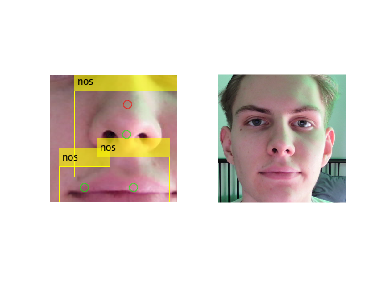

nos_warunek_1 = poleNosa > proporcjaObszaruTwarzyiNosa*poleTwarzy;
noseBBox2A = noseBBox2(nos_warunek_1,:);
RGB2 = faceIM;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2A,'nos');
subplot(1,2,2);imshow(RGB2)

algorytm błędnie pozostawił znalezione nosy

własny 2

detector = vision.CascadeObjectDetector();
RGB = imread('snapshot2.png');
bboxes = detector(RGB);
liczbaWykrytychTwarzy = size(bboxes,1)

liczbaWykrytychTwarzy = 1


GRAY=rgb2gray(RGB);
corners = detectMinEigenFeatures(GRAY);
corners

corners =   1038×1 cornerPoints array with properties:

    Location: [1038×2 single]
      Metric: [1038×1 single]
       Count: 1038


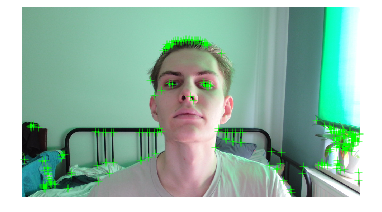

figure; imshow(RGB)
hold on; plot(corners.selectStrongest(250))

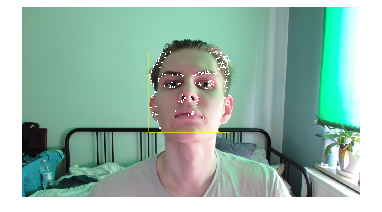


corners2 = detectMinEigenFeatures(GRAY, 'ROI', bboxes(1, :));
xyPoints = corners2.Location;
bboxPoints = bbox2points(bboxes(1, :));
bboxPolygon = reshape(bboxPoints', 1, []);
RGB2 = insertShape(RGB, 'Polygon', bboxPolygon, 'LineWidth', 3);
RGB2 = insertMarker(RGB2, xyPoints, '+', 'Color', 'white');
figure; imshow(RGB2)

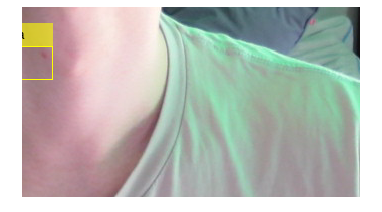


noseDetector = vision.CascadeObjectDetector('Nose');
mouthDetector = vision.CascadeObjectDetector('Mouth');
noseBBox1=step(noseDetector, RGB);
mouthBBox1=step(mouthDetector, RGB);
RGB2 = RGB;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox1,'nos');
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',mouthBBox1,'usta');
imshow(RGB2)

nos - 2

usta - 7

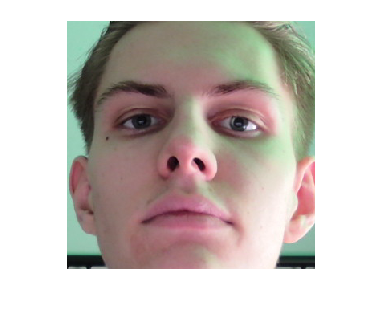

faceIM = imcrop(RGB, bboxes(1, :)); % wycięcie obszaru twarzy
imshow(faceIM)

% zawężenie detekcji cech tylko do obszaru twarzy
noseBBox2=step(noseDetector, faceIM);
mouthBBox2=step(mouthDetector, faceIM);
% dodatkowe warunki weryfikujące cechy
RGB2 = faceIM;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2,'nos');
figure;subplot(1,2,1);imshow(RGB2)
srodekTwarzy = [bboxes(1,3)/2 bboxes(1,4)/2]

srodekTwarzy =    154   154


% uwaga bboxes to wspolrzedne przed wycieciem twarzy
srodekNosa = [noseBBox2(:,1)+noseBBox2(:,3)/2 noseBBox2(:,2)+noseBBox2(:,4)/2]

srodekNosa =    149   174


hold on
plot(srodekTwarzy(1),srodekTwarzy(2),'ro')
plot(srodekNosa(:,1),srodekNosa(:,2),'go')
proporcjaObszaruTwarzyiNosa = 0.3;
poleTwarzy = bboxes(1,3).*bboxes(1,4)

poleTwarzy = 94864

poleNosa = noseBBox2(:,3).*noseBBox2(:,4)

poleNosa = 7332

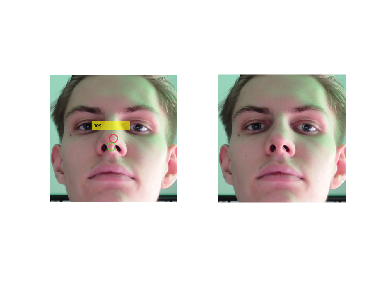

nos_warunek_1 = poleNosa > proporcjaObszaruTwarzyiNosa*poleTwarzy;
noseBBox2A = noseBBox2(nos_warunek_1,:);
RGB2 = faceIM;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2A,'nos');
subplot(1,2,2);imshow(RGB2)

algorytm poprawnie ograniczył do 1 nosa

własny 3

detector = vision.CascadeObjectDetector();
RGB = imread('snapshot3.png');
bboxes = detector(RGB);
liczbaWykrytychTwarzy = size(bboxes,1)

liczbaWykrytychTwarzy = 1


GRAY=rgb2gray(RGB);
corners = detectMinEigenFeatures(GRAY);
corners

corners =   1152×1 cornerPoints array with properties:

    Location: [1152×2 single]
      Metric: [1152×1 single]
       Count: 1152


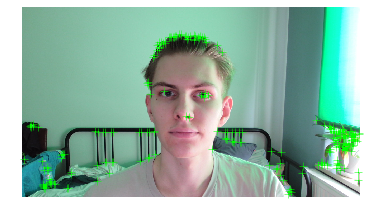

figure; imshow(RGB)
hold on; plot(corners.selectStrongest(250))

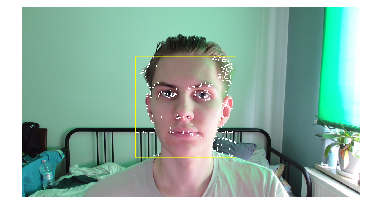


corners2 = detectMinEigenFeatures(GRAY, 'ROI', bboxes(1, :));
xyPoints = corners2.Location;
bboxPoints = bbox2points(bboxes(1, :));
bboxPolygon = reshape(bboxPoints', 1, []);
RGB2 = insertShape(RGB, 'Polygon', bboxPolygon, 'LineWidth', 3);
RGB2 = insertMarker(RGB2, xyPoints, '+', 'Color', 'white');
figure; imshow(RGB2)

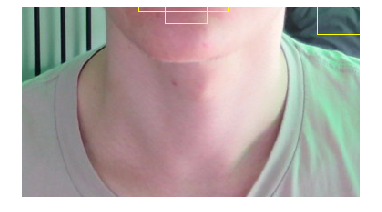


noseDetector = vision.CascadeObjectDetector('Nose');
mouthDetector = vision.CascadeObjectDetector('Mouth');
noseBBox1=step(noseDetector, RGB);
mouthBBox1=step(mouthDetector, RGB);
RGB2 = RGB;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox1,'nos');
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',mouthBBox1,'usta');
imshow(RGB2)

nos - 3

usta - 9

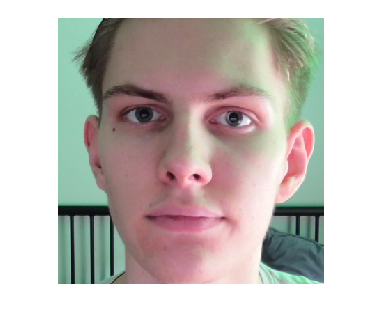

faceIM = imcrop(RGB, bboxes(1, :)); % wycięcie obszaru twarzy
imshow(faceIM)

% zawężenie detekcji cech tylko do obszaru twarzy
noseBBox2=step(noseDetector, faceIM);
mouthBBox2=step(mouthDetector, faceIM);
% dodatkowe warunki weryfikujące cechy
RGB2 = faceIM;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2,'nos');
figure;subplot(1,2,1);imshow(RGB2)
srodekTwarzy = [bboxes(1,3)/2 bboxes(1,4)/2]

srodekTwarzy =   190.5000  190.5000


% uwaga bboxes to wspolrzedne przed wycieciem twarzy
srodekNosa = [noseBBox2(:,1)+noseBBox2(:,3)/2 noseBBox2(:,2)+noseBBox2(:,4)/2]

srodekNosa =   145.0000  280.0000
  180.5000  224.5000


hold on
plot(srodekTwarzy(1),srodekTwarzy(2),'ro')
plot(srodekNosa(:,1),srodekNosa(:,2),'go')
proporcjaObszaruTwarzyiNosa = 0.3;
poleTwarzy = bboxes(1,3).*bboxes(1,4)

poleTwarzy = 145161

poleNosa = noseBBox2(:,3).*noseBBox2(:,4)

poleNosa =         3696
       10323


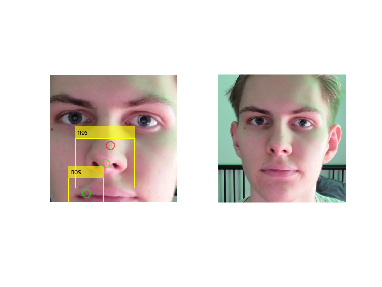

nos_warunek_1 = poleNosa > proporcjaObszaruTwarzyiNosa*poleTwarzy;
noseBBox2A = noseBBox2(nos_warunek_1,:);
RGB2 = faceIM;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2A,'nos');
subplot(1,2,2);imshow(RGB2)

algorytm dobrze znalazł jeden nos, ale nie usunął nosa z ust

Komentarz do punktów charakterystycznych, dla wszystkich przykładów:

Nie wszystkie punkty charakterystyczne, odowiadają atrybutom stałym, część z nich umiejscowiłą się w okolicach takich jak policzki czy włosy (szczególnie z boku)

Punkty koncentrują się głównie o okolicach oczu i nosa

Przykłady gdzie twarz nie jest poprawnie wykrywana lub nie wykryte są nos i usta.

Najczęsciej było to spowodowane zakryciem częsci twarzy lub wyjściem części twarzy poza ekran

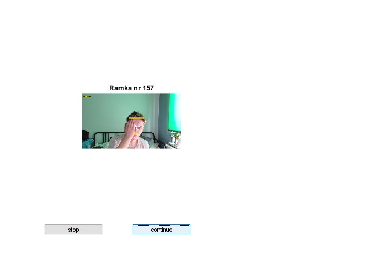

I1 = imread('mistake1.jpg');
I2 = imread('mistake2.jpg');
I3 = imread('mistake3.jpg');
figure; imshow(I1)

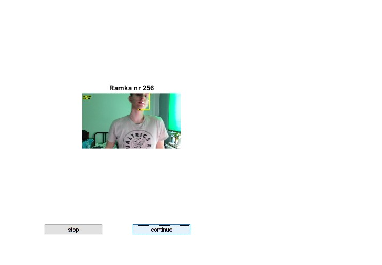

figure; imshow(I2)

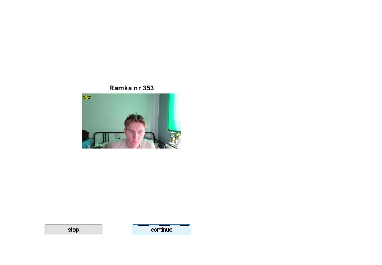

figure; imshow(I3)

Podsumowanie

Rezultaty - powyżej

Analiza i wnioski:

- wyżej

- Detektory nie zawsze dobrze znajdowały elementy, może to być spowodowane różnicami w oświetleniu na zdjęciu oraz np. niestandardowymi kontami klatek na których była twarz

- Położenie nosa i twarzy w relacji do siebie, odpowiednia relacja szerokości i długości znalezionej ramki

- algorytm działał stosunkowo dobrze, jedyne problemy można było zauważyć podczas wyjścia częsci twarzy poza kadr, mocnych różnic jasnośći czy zakrycia częsci twarzy, przykładowym rozwiązaniem problemu przy zakryciu twarzy może być zapamiętanie pozycji nosa i ust i przesuwanie jej zgodnie z wykrytą ramką twarzy (zakładamy, że twarz udało się wykryć), przy problematycznym kontraście chyba jedynym roziązaniem jest normalizacja obrazu i zastosowanie filtrów do ujednolicenia klatki, zanim przejdziemy do segmentacji

Pytania

- - 

- 2 modele predycji AU: statyczny - na podstawie jednego obrazu, dynamiczny - bierze pod uwagę znormalizowany obraz osoby na podstawie sekwencji wideo; PDM - parametry opisujące twarz, można wyróżnić wsród nich m.in umiejscowienie twarzy na obrazie (rotacja, translacja) i deformacje twarzy w wyniku mimiki; FACS - sposób na zakodowanie mimiki twarzy co następnie ułatwia klasyfikacje

- Na czym polega odróżnianie konkretnych AU od siebie, jakie parametry stanowią o wystąpieniu danego AU?